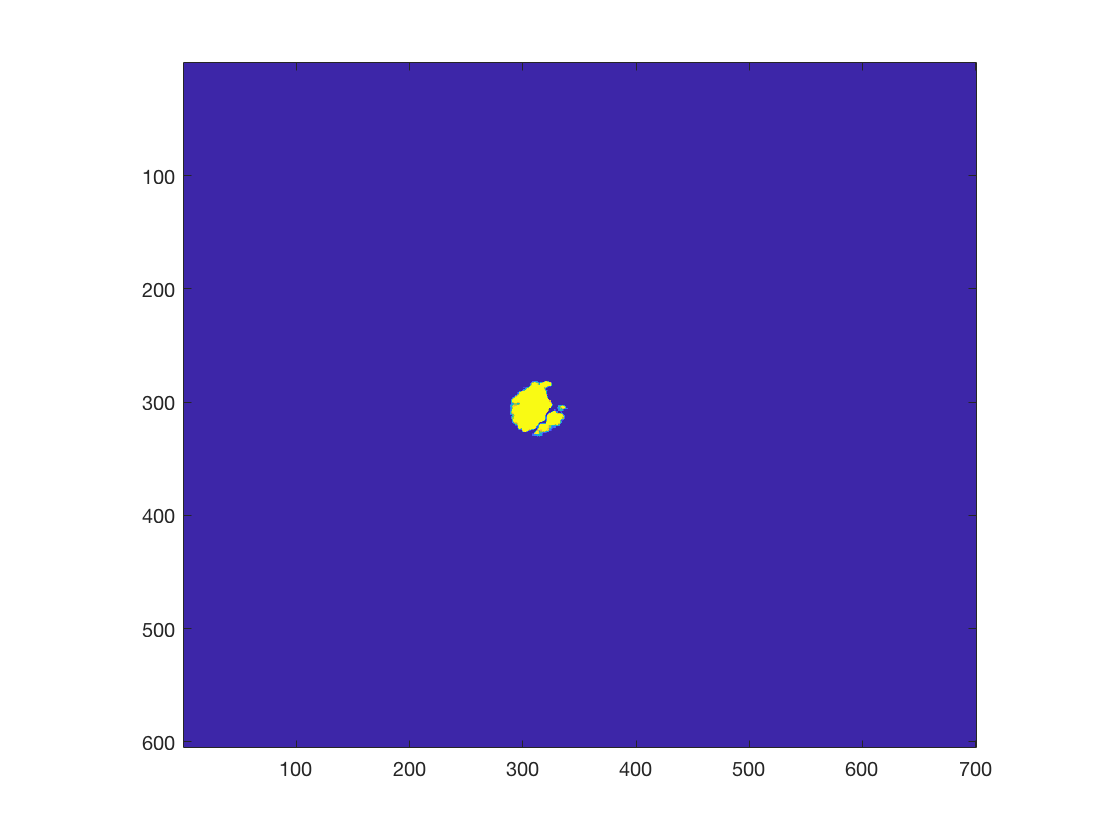

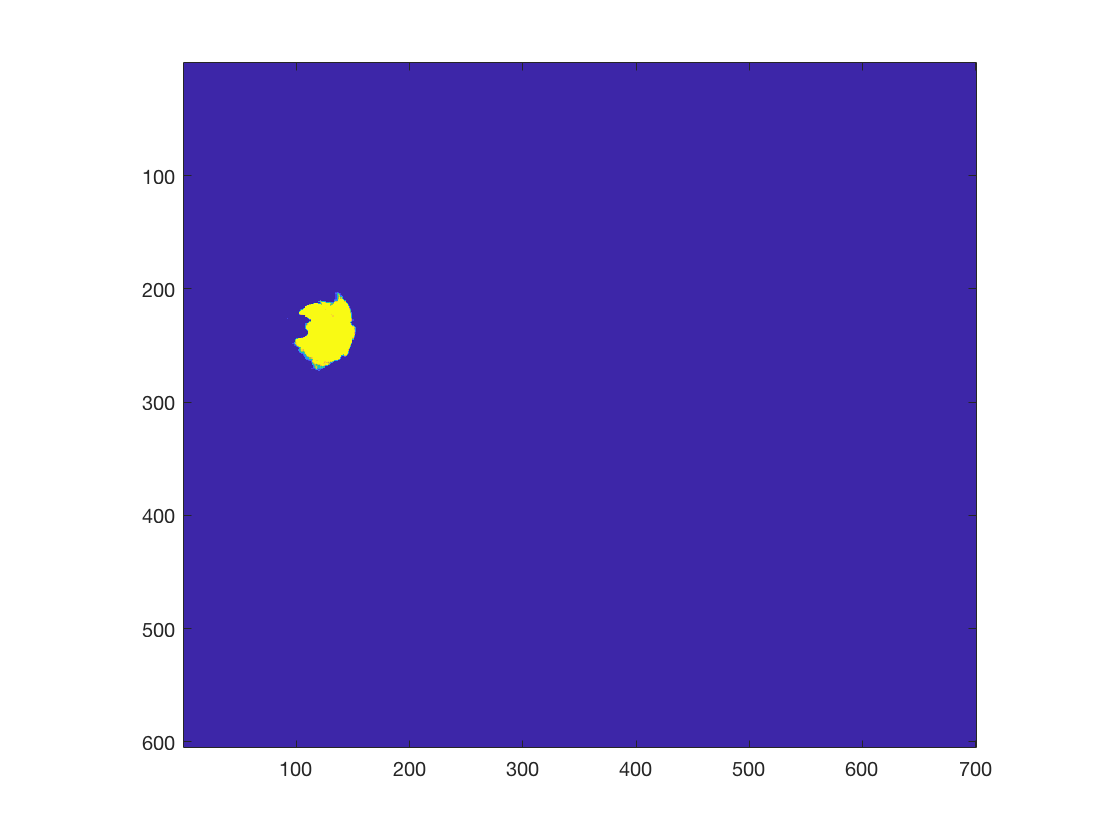

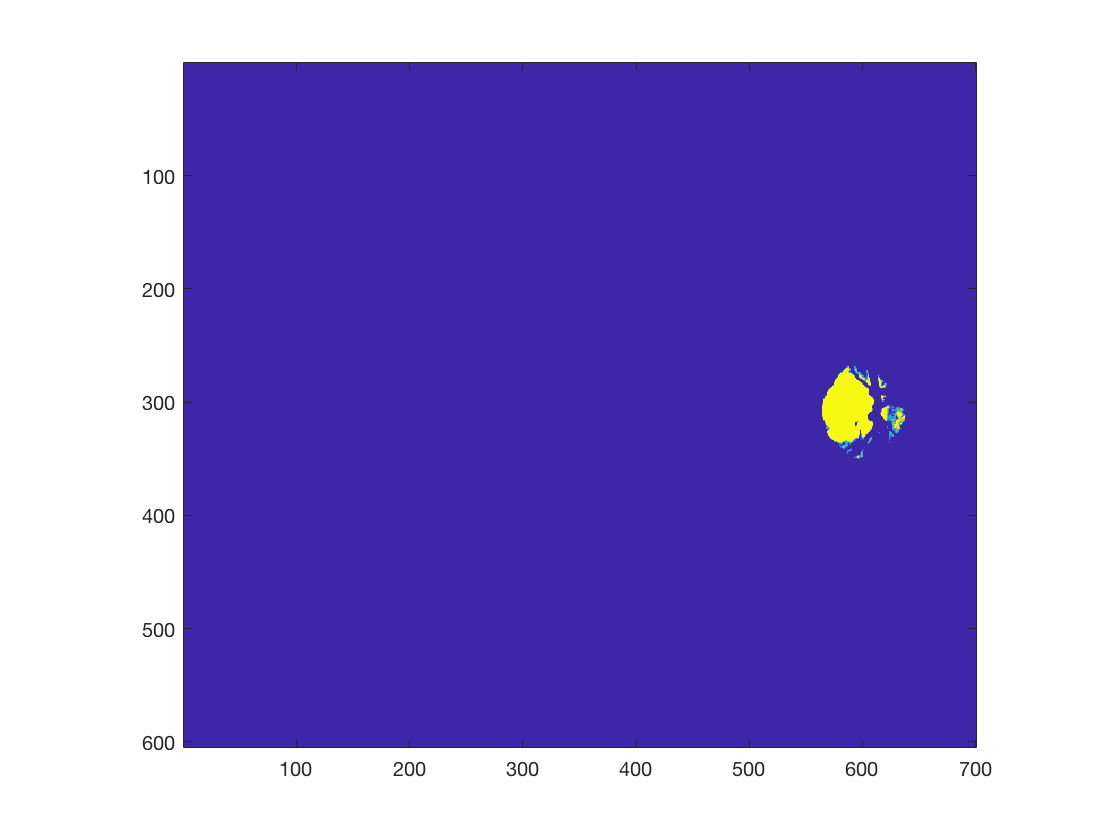

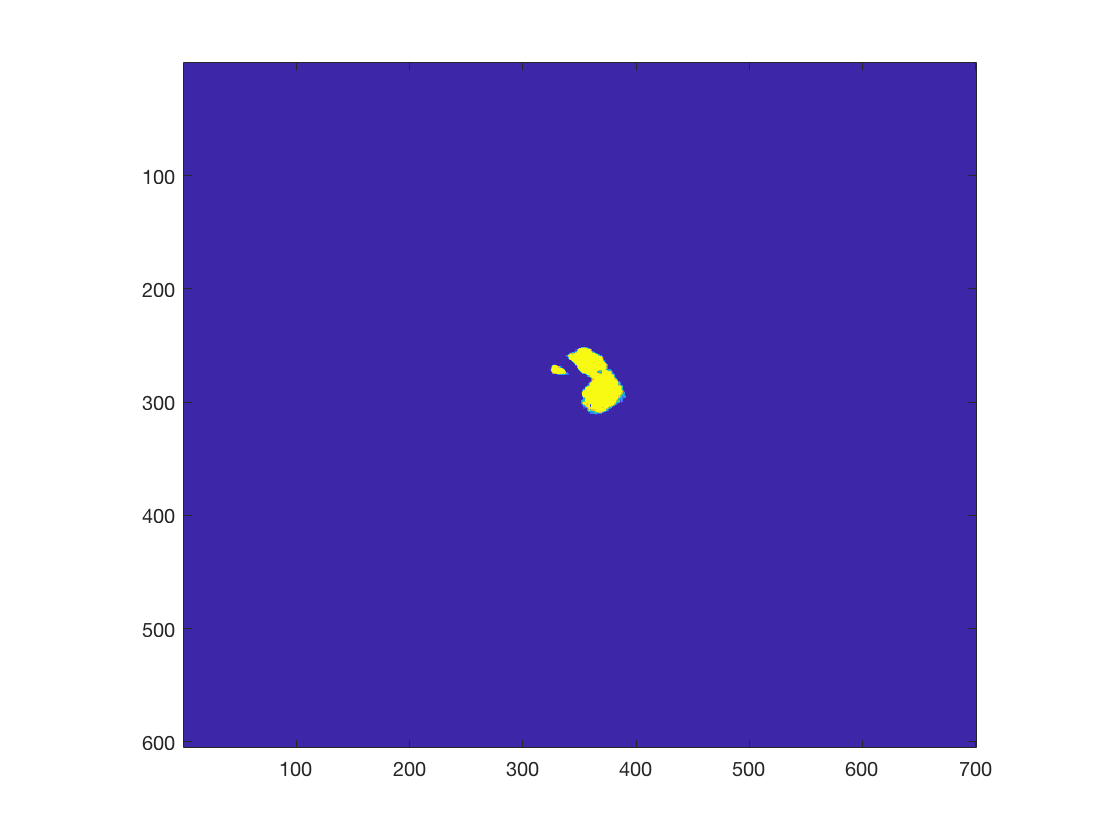

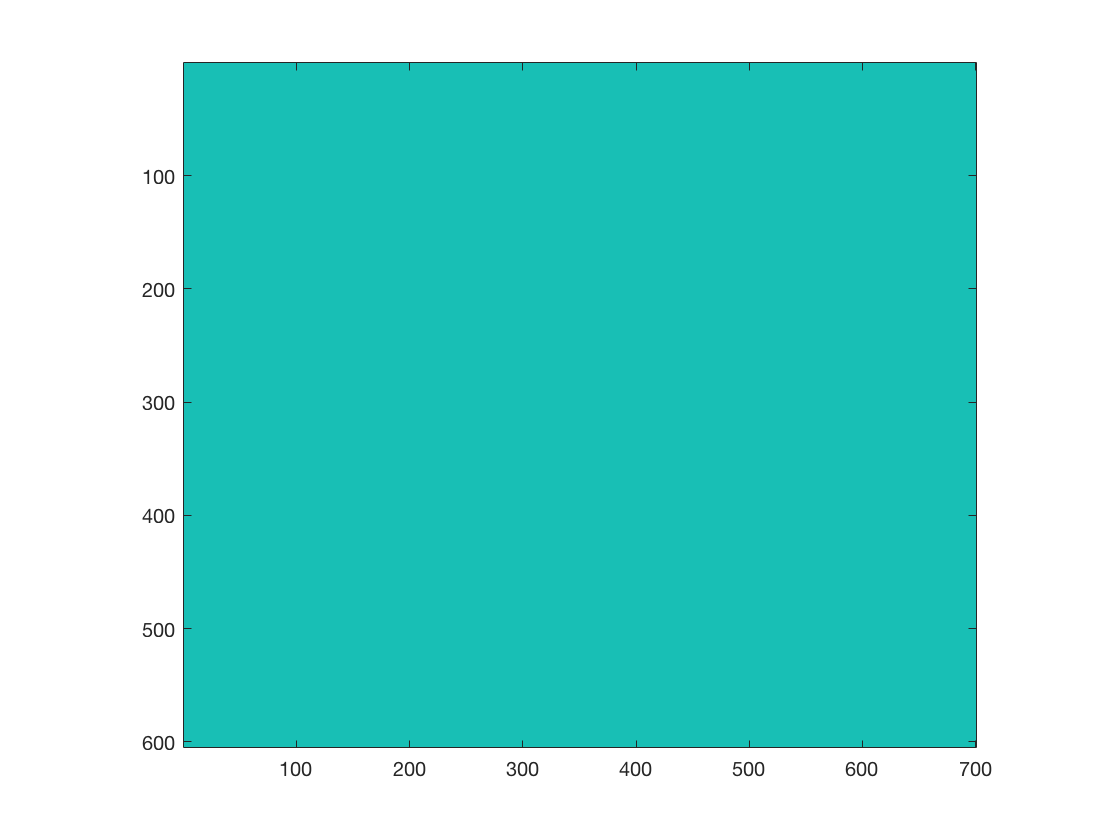

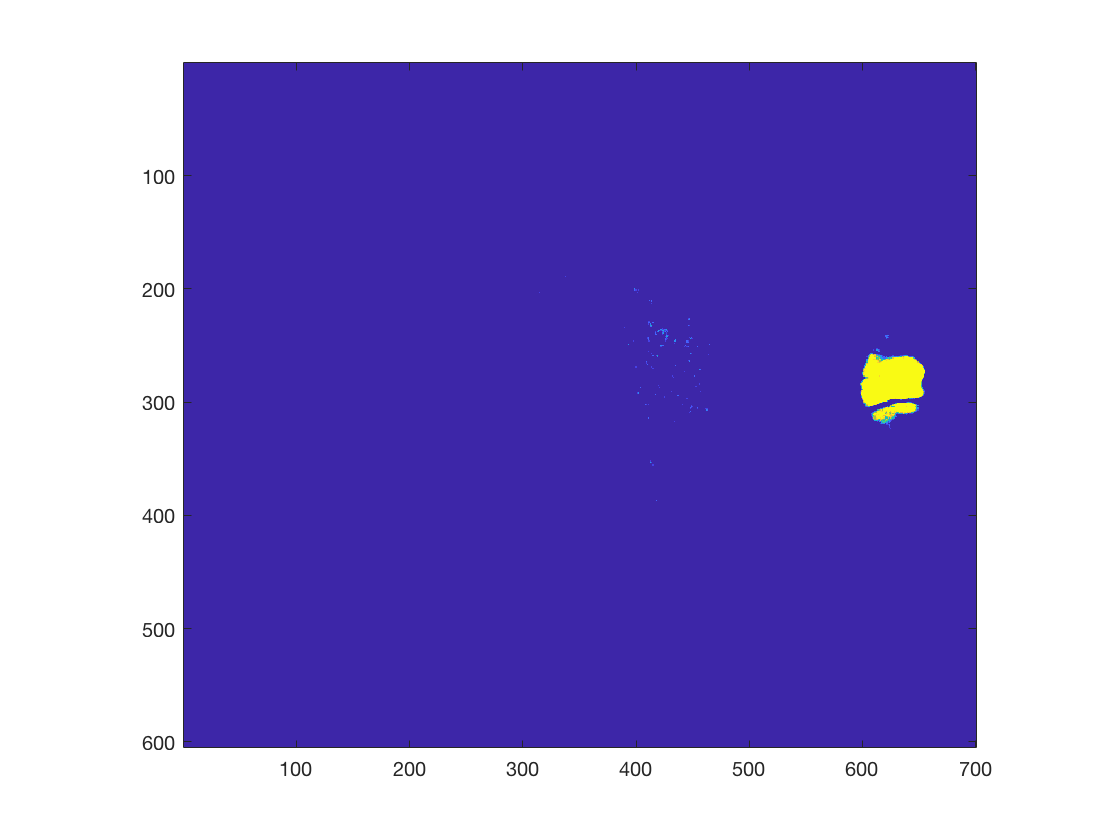

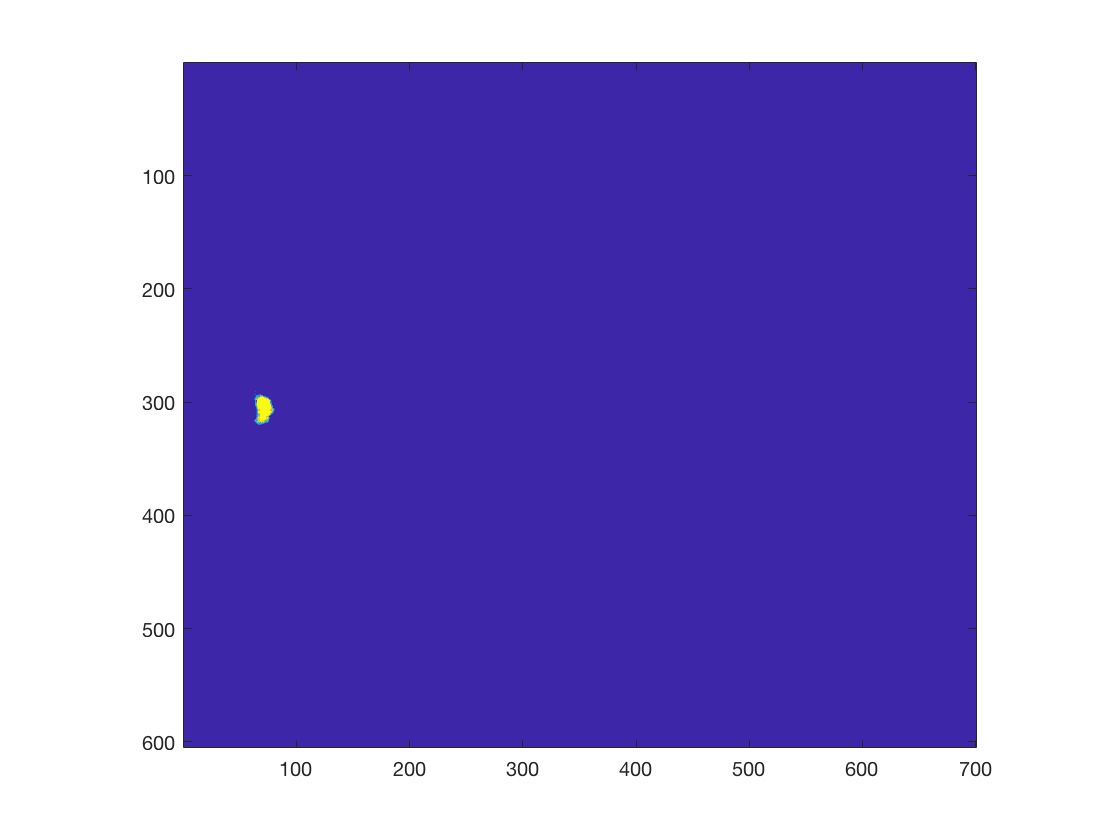

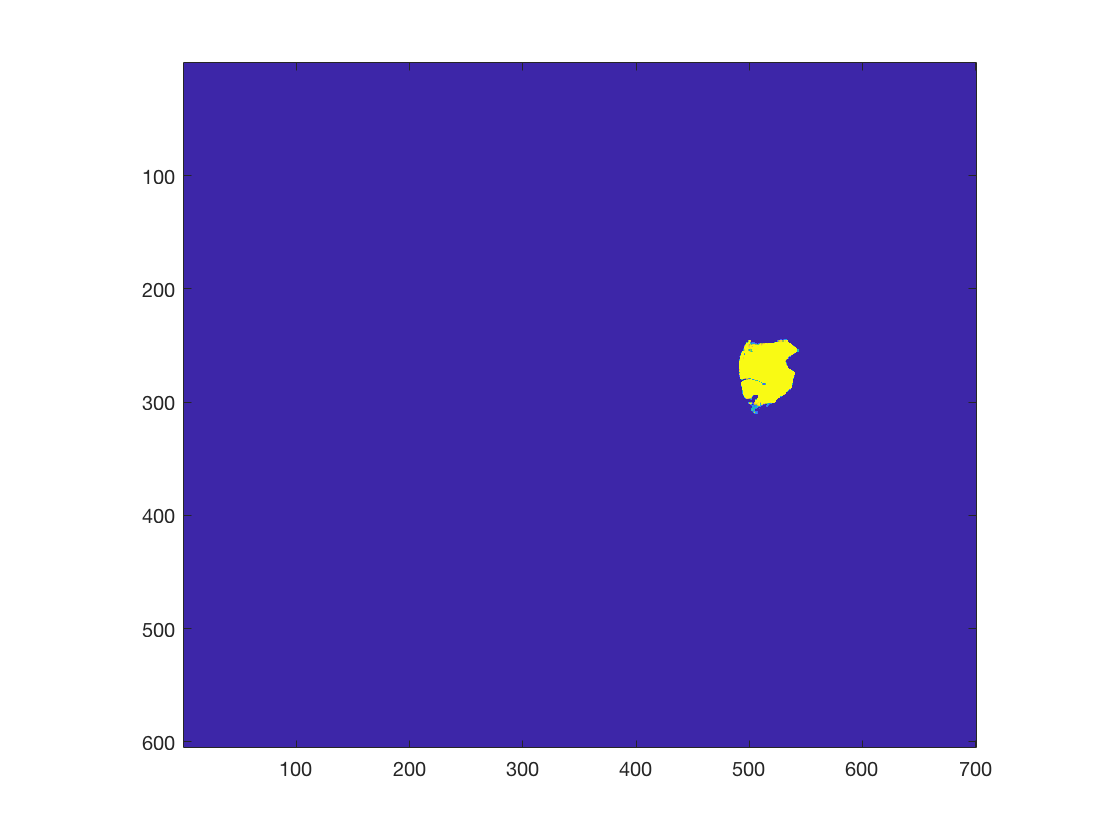

path = '/Users/sparshagarwal/OneDrive/Spring 2018/CS 567/distributed';

% This will generate a list of all the files
files = dir(sprintf('%s/img*.ppm',path));
num_files = length(files);

for i=1:num_files
% fig_panel_count = 1;
% for i=[1:4, (num_files-3):num_files]
    img = double(imread(sprintf('%s/%s',path, files(i).name)));
%     img = img-imgaussfilt(img, 3);
    
    lower = 160;
    upper = 170;
    % img = 0.005*img_029(:,:,1)+1.55*img_029(:,:,2)+0.005*img_029(:,:,3);
    img = img(:,:,2);
    img(img<lower) = 0;
    img(img>upper) = 255;
    img(img>=lower & img<=upper) = (255/(upper-lower))*img(img>=lower & img<=upper) -255*lower/(upper-lower);
    
    figure
    imagesc(img)
    axis('image')
    
    img(img<=250) = 0;
    img(img>250) = 1;
%     
%     figure
%     imagesc(img)
%     axis('image')
end

% figure
% colormap('gray')
% % minint=min(min(gray(:))); 
% % gray=gray-minint; 
% % maxint=max(max(gray(:))); 
% % gray=gray/maxint*63; 
% imagesc(gray)
% axis('image')